## Opgave 2

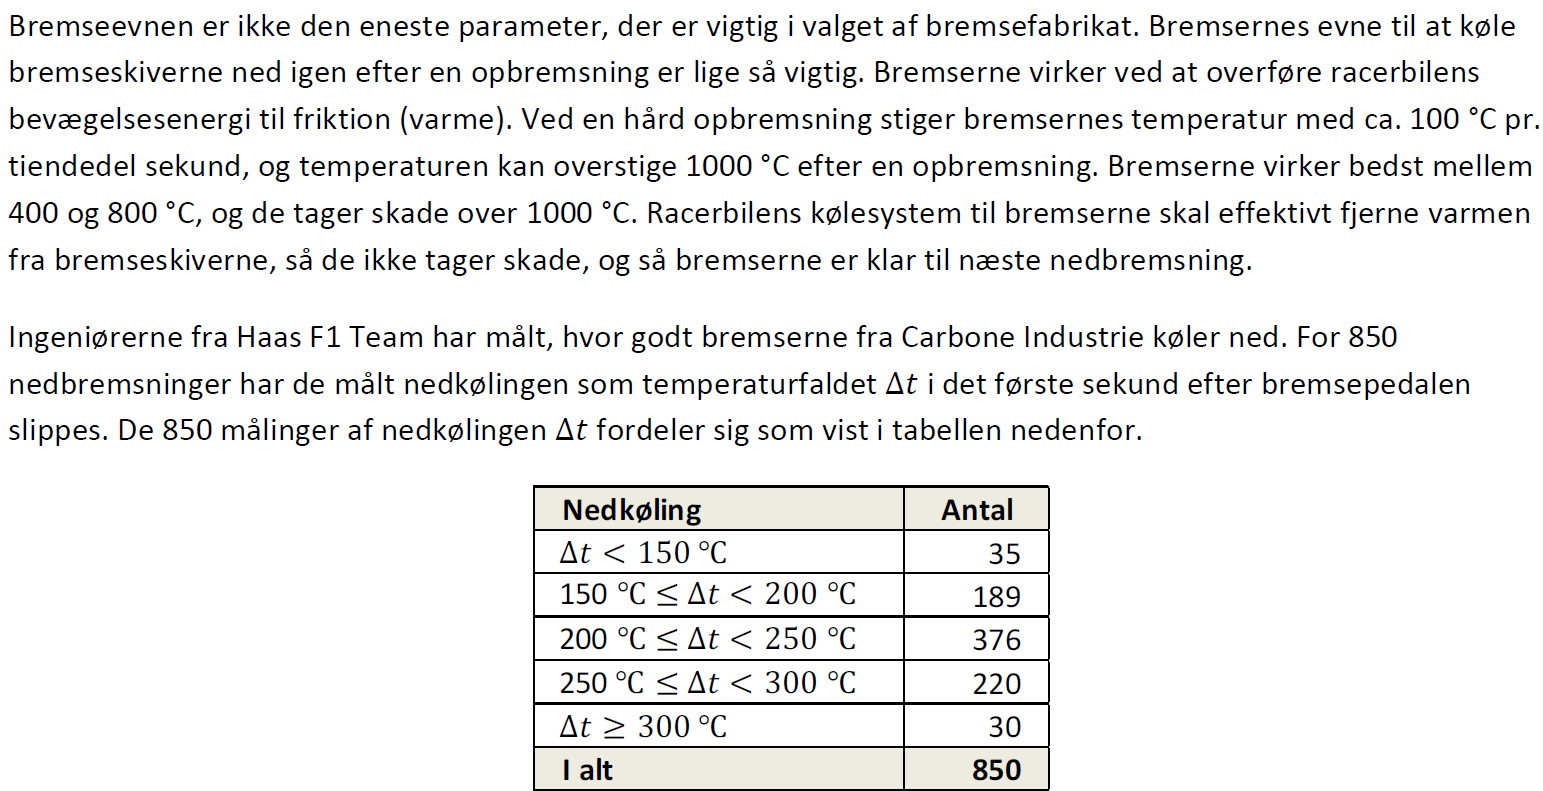

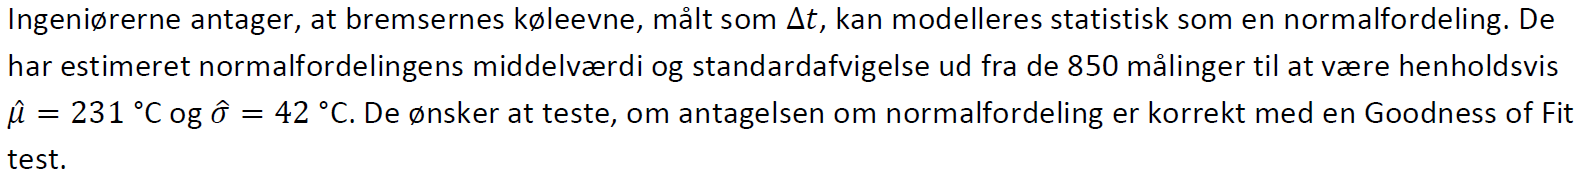

### a)

Giv på baggrund af observationerne i tabellen din umiddelbare vurdering af, om ingeniørernes antagelse virker rimelig.

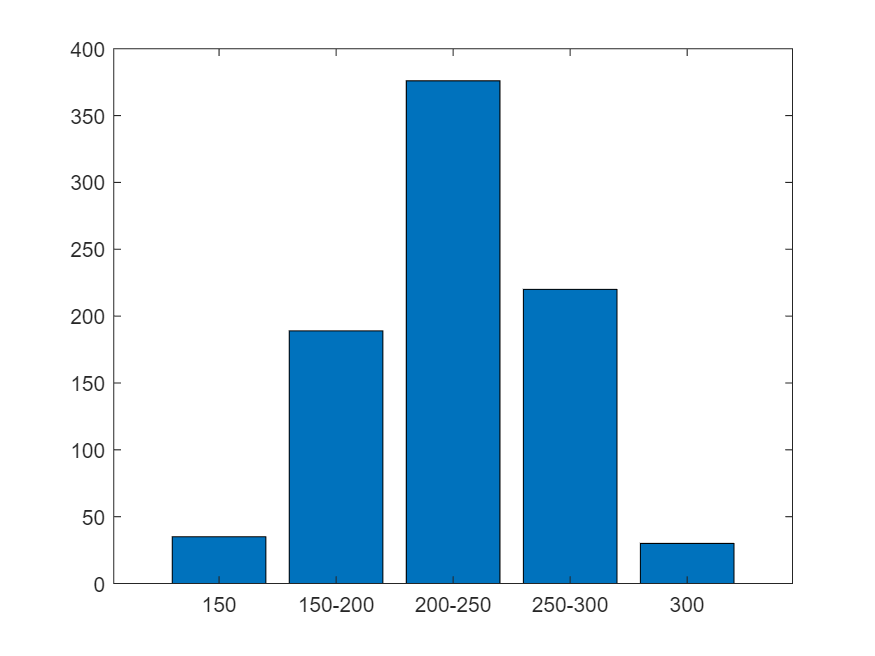

clear
format shortg

data = [35, 189, 376, 220, 30];
bins = categorical({'150', '150-200','200-250', '250-300','300'});% 1:length(data);%
bar(bins, data)

ANtagelserne virker rimelige da vi ser en normal fordeling i histogramet med en middel værdi omkring de 231.

### b)

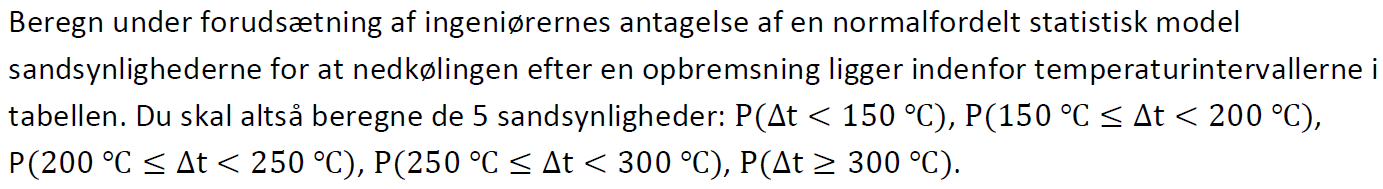

P = 0;
Ps = 0;
interval = 150:50:300

interval =    150   200   250   300


for i = 1:length(data)
    if i == length(data)
        P = normcdf(inf,231,42) - sum(Ps);
    else
        P = normcdf(interval(i),231,42) - sum(Ps);
    end
    Ps(i) = P;
end
Ps

Ps =      0.026892      0.20334      0.44427      0.27529     0.050206


% P200 = normcdf(200,231,42) - P150
% sand = data/sum(data) * 100
% table(sand',VariableNames={'P%'},RowNames={'<150', '150-200','200-250', '250-300','300<'})

### c)

Beregn under antagelse af ovennævnte normalfordeling det forventede antal nedbremsninger i hver af de fem temperaturintervaller, når der i alt foretages 850 nedbremsninger.

% for i = 1:length(sand)
%     antal(i) = norminv(sand(i)/100,231,42);
% end
% antal
forvent = sand/100 * sum(data)

Unrecognized function or variable 'sand'.

### d)

Opstil formlen for teststørrelsen for en Goodness of Fit test og oplys teststørrelsens fordeling og antal frihedsgrader.

### e)

Beregn den kritiske grænse for testen på 5 % signifikansniveau.

### f)

Beregn teststørrelsens værdi og konkludér på testen.

## Opgave 3

### a)

clear
data = xlsread("Statestik\Eksamens sæt\17E\Data_M4STI1_2017E.xlsx");
data_size = size(data)

data_size =     60    12


Brembo = data(1:20,11)

Brembo =    92.5320
   92.8750
   94.4790
   92.1390
   93.7850
   93.3090
   92.7660
   91.9430
   92.7160
   92.9130


leng = length(Brembo)

leng = 20

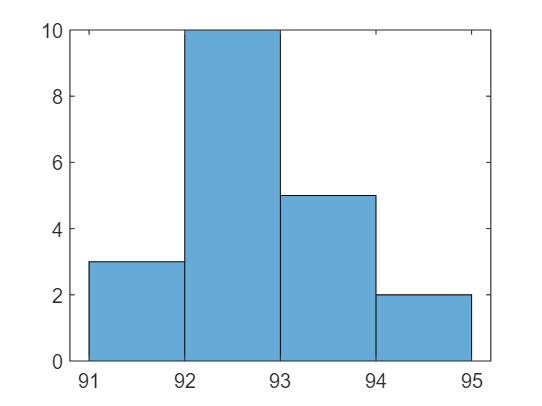




histogram(Brembo)

middel = mean(Brembo)

middel = 92.7978

Median = median(Brembo)

Median = 92.8205

sigma_2 = var(Brembo)

sigma_2 = 0.6726

sigma = std(Brembo) % std(Brembo,0) = s % std(Brembo,1) = sigma

sigma = 0.8201

data_min = min(Brembo)

data_min = 91.1640

data_max = max(Brembo)

data_max = 94.4790

Cl = data(1:20,12)

Cl =    90.2740
   95.8780
   92.0530
   94.2860
   89.8920
   94.6340
   95.8220
   95.3620
   90.3720
   93.9600


leng = length(Cl)

leng = 20

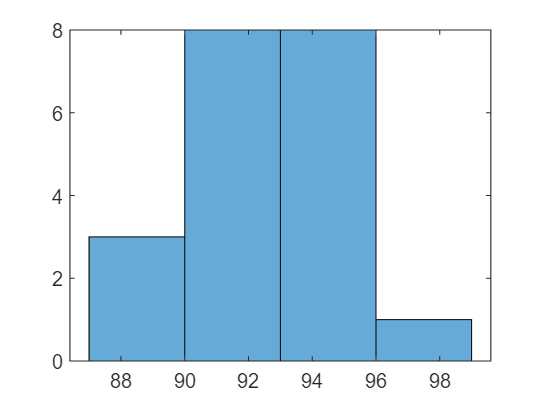


histogram(Cl)

middel = mean(Cl)

middel = 92.9125

Median = median(Cl)

Median = 92.5085

sigma_2 = var(Cl)

sigma_2 = 6.8375

sigma = std(Cl)

sigma = 2.6149

data_min = min(Cl)

data_min = 87.9030

data_max = max(Cl)

data_max = 98.2730


disp(' ')


[middel, med, varians, stdafv, data_max, data_min] = Descriptor(Brembo)

Unrecognized function or variable 'Brembo'.

### b)

Beregn 95 % konfidensinterval for populationsmiddelværdien for omgangstider med hhv. Brembo og CI bremserne. Hvad fortæller dine resultater fra delspørgsmål a. og b. dig om forskelle på de to bremsefabrikater?

alpha = 0.05;
n_brembo = length(Brembo)

n_brembo = 20

n_Cl = length(Cl)

n_Cl = 20


df = n_brembo-1 % degrees of freedom

df = 19


z_1_brembo = -tinv(1 - alpha / 2, df) % 

z_1_brembo = -2.0930

z_2_brembo = tinv(1-alpha/2,n_brembo-1)

z_2_brembo = 2.0930

z_1_Cl = -tinv(1-alpha/2,n_Cl-1)

z_1_Cl = -2.0930

z_2_Cl = tinv(1-alpha/2,n_Cl-1)

z_2_Cl = 2.0930


sigma_brembo = std(Brembo)

sigma_brembo = 0.8201

sigma_Cl = std(Cl)

sigma_Cl = 2.6149



err_brembo_low = z_1 * sigma_brembo / sqrt(n_brembo)

err_brembo_low = -0.3838

err_brembo_high = z_2 * sigma_brembo / sqrt(n_brembo)

err_brembo_high = 0.3838


err_Cl_low = z_1 * sigma_Cl / sqrt(n_Cl)

err_Cl_low = -1.2238

err_Cl_high = z_2 * sigma_Cl / sqrt(n_Cl)

err_Cl_high = 1.2238



middel_cl = [mean(Cl) + err_Cl_low, mean(Cl) + err_Cl_high 
             mean(Brembo) + err_brembo_low, mean(Brembo) + err_brembo_high]

middel_cl =    91.6888   94.1363
   92.4140   93.1817
